# Taller 3: Estadísticas hidrológicas y extremos

#### Thomas Felipe Aranda Herrera

clear;
clc;

Considere los siguientes datos de caudal máximo diario anual del río Mosa en la estación de Eysden en la frontera entre los Países Bajos y Bélgica (descarga promedio diaria en m3/s).

% Se cargan los datos de caudal.
data = load('caudales_ext.m');

1). Pruebe si estos valores pueden ser modelados como variables estocásticas independientes.

% Se crean las variables de tiempo [t] y caudal [x].
t = data(:,1);
x = data(:,2);

% Se calcula la media de los caudales [xm]. Posteriormente se generan los
% ciclos Q1 y Q2, que almacenan los valores del numerador y denominador del
% test de independencia [Q], respectivamente.
xm = mean(x)

xm = 1475

x_std = std(x)

x_std = 512.0686

Q1 = zeros(1,length(x));
Q2 = zeros(1,length(x));
for i = 1:length(x)-1
    Q1(i) = (x(i)-x(i+1))^2;
end

for i = 1:length(x)
    Q2(i) = (x(i)-xm)^2;
end

% Finalmente se calcula Q al dividir las sumatoria de Q1 sobre Q2.
Q = sum(Q1)/sum(Q2)

Q = 2.1541

% Q = 2.1541
 

% se calcula Q'= Qp 
Qp = (Q-2)/(2*sqrt((length(x)-2)*(length(x)^2 - 1)))

Qp = 2.0960e-04


% Al consultar el valor crítico de Von Neumann para un n=52 y una
% significancia de 0.05 se obtiene:

Qc = 1.5477;

% Como Qp < Qc, implica que los datos son independientes entre sí.


2). Pruebe si se puede detectar una tendencia.

% Se utiliza el test de Mann-Kendall para evaluar si hay tendencia.
% Si h = 0, no hay tendencia. Si h = 1 hay tendencia.
[h, p] = Mann_Kendall(x,0.05)

h = logical
   0


p = 0.4029


disp('Hipótesis nula (H0): No hay tendencia');

Hipótesis nula (H0): No hay tendencia


disp('Hipótesis alternativa (H1): Hay tendencia');

Hipótesis alternativa (H1): Hay tendencia



% De acuerdo con lo anterior, no hay tendencia en la serie de datos.


3). Grafique los datos en papel de probabilidad Gumbel y determina los parámetros de la distribución Gumbel.

¿Cuál es la estimación de la inundación de 1000 años?

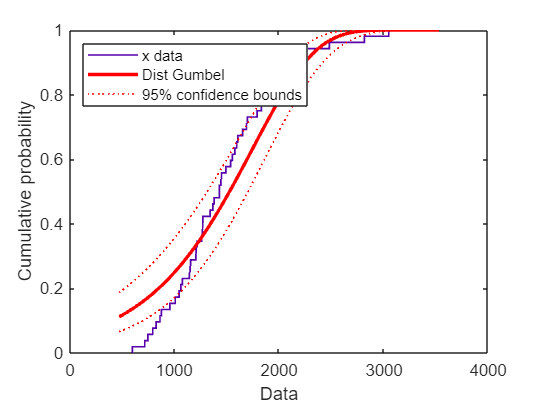

S =   ExtremeValueDistribution

  Extreme Value distribution
       mu = 1746.75   [1573.31, 1920.19]
    sigma = 599.287   [499.612, 718.847]


% Utilizando la herramienta Distribution Fitter, se importa la función
% createFit, en donde se muestra el ajuste de la distribución Gumbel a los
% datos analizados
S = createFit(x)

[x_gumbel] = evfit(x)

x_gumbel = 1.0e+03 *

    1.7468    0.5993


% Los estadísticos que arroja son:
xm_gumbel = x_gumbel(1)

xm_gumbel = 1.7468e+03

x_std_gumbel = x_gumbel(2)

x_std_gumbel = 599.2866


% Para un periodo de retorno de 1000 años, se calcula la probabilidad
% mediante P = 1/Tr

Tr = 1000;
P_1000 = 1/Tr

P_1000 = 1.0000e-03


% Se calcula el caudal de inundación reemplazando 1-P_1000 en la inversa de
% la distribución Gumbel.
Qi = vpa(evinv(1-P_1000, xm_gumbel,x_std_gumbel),6)

$$Qi = 2904.96$$

4). Determine los parámetros de la distribución Gumbel mediante regresión lineal de Qmax contra _______con i siendo el rango del máximo más pequeño. Estima la inundación de 1000 años y sus límites de confianza del 95%.

% Se crea el vector donde se almacenarán los datos de la regresión sugerida
x4 = zeros(length(x),1);

% Se reemplazan los valores en cada posición del vector
for i = 1:length(x4)
    x4(i) =-log(-log(i/(length(x4)+1)));
end
x4

x4 =    -1.3788
   -1.1870
   -1.0549
   -0.9493
   -0.8590
   -0.7787
   -0.7053
   -0.6370
   -0.5727
   -0.5114


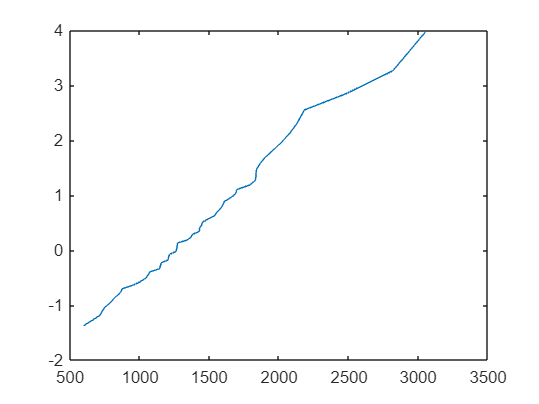


% Se grafican los valores calculados vs los valores de Qmax
plot(sort(x), x4)


% Se realiza la regresión linear utilizando la función fitlm y se grafica
mdl = fitlm(sort(x), x4)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE         tStat       pValue  
                   _________    __________    _______    __________

    (Intercept)      -2.8192      0.049951    -56.438    6.0259e-47
    x1             0.0022837    3.2025e-05      71.31    5.7917e-52


Number of observations: 52, Error degrees of freedom: 50
Root Mean Squared Error: 0.117
R-squared: 0.99,  Adjusted R-Squared: 0.99
F-statistic vs. constant model: 5.09e+03, p-value = 5.79e-52

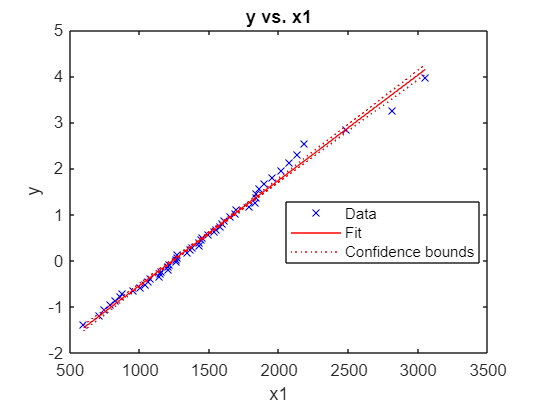

plot(mdl)


% De la tabla de coeficientes se extrae la pendiente (m) y el intercepto
% (b)
tabla = mdl.Coefficients

tabla = 2×4 table
                   Estimate         SE         tStat       pValue  
                   _________    __________    _______    __________

    (Intercept)      -2.8192      0.049951    -56.438    6.0259e-47
    x1             0.0022837    3.2025e-05      71.31    5.7917e-52


m = tabla{2,1}

m = 0.0023

b = tabla{1,1}

b = -2.8192


% Se calculan Beta y mu, parámetros de la distribución Gumbel
beta = 1/m

beta = 437.8812

mu = b + log(beta)

mu = 3.2628


% Se calcula el caudal para 1000 años mediante:

Q1000 = vpa(mu - beta*log(-log(1-0.001)),6)

$$Q1000 = 3027.82$$

5). Determine los parámetros de la distribución Gumbel con el método de momentos. Estima la inundación de 1000 años y sus límites de confianza del 95%.

% En primer lugar se muestra el promedio y la desviación estándar de la
% muestra:

xm

xm = 1475

x_std

x_std = 512.0686


% Ahora se calculan los parámetros a y b de la dist Gumbel

a_G = (sqrt(6)/pi())*x_std

a_G = 399.2583


b_G = xm - 0.5772*a_G

b_G = 1.2445e+03


% Ahora se estima la inundación en 1000 años
T = 1000;
Q_1000 = vpa(b_G - a_G*log(log(T/(T-1))),6)

$$Q\_1000 = 4002.33$$

Q2_1000 = vpa(xm - x_std*((sqrt(6)/pi())*(0.5772+log(log(T/(T-1))))),6)

$$Q2\_1000 = 4002.33$$

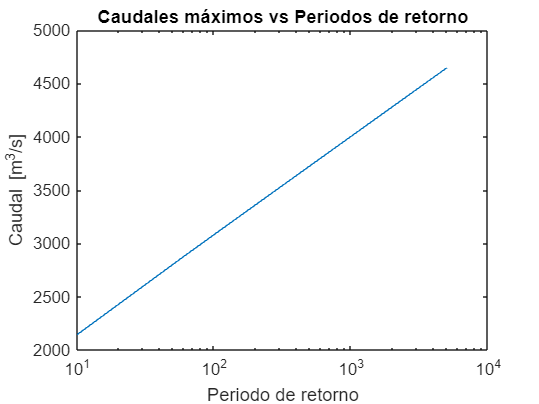


u = linspace(10,5000,100);
Q_plot = b_G - a_G.*log(log(u./(u-1)));

semilogx(u,Q_plot)
xlabel('Periodo de retorno')
ylabel('Caudal [m^{3}/s]')
title('Caudales máximos vs Periodos de retorno')

6). Estima la inundación de 1000 años asumiendo una distribución lognormal de los valores máximos.

% Se calculan los parámetros de la distribución lognormal
sigma_log =sqrt(log(1+(x_std/xm)^2))

sigma_log = 0.3373

mu_log = log(xm)-0.5*log(1+(x_std/xm)^2)

mu_log = 7.2395



q = 1-1/T

q = 0.9990


% Se calcula la el caudal para un periodo de retorno de 1000 años mediante:
Q_1000_log = vpa(exp(mu_log + norminv(q)*sigma_log),6)

$$Q\_1000\_log = 3951.95$$

7). Prueba si los datos pueden considerarse como resultados de una distribución Gumbel.

% En la siguiente línea se ajustan los datos a la distribución y se realiza la
% prueba Chi2 para determinar si se ajustan los datos a esta distribución.
[h7,p7] = chi2gof(x,"CDF",fitdist(x,"ExtremeValue"),"Alpha",0.05)

h7 = 1

p7 = 0.0300

% Lo anterior indica que los datos NO se ajustan a la distribución Gumbel.

8). Prueba si los datos pueden considerarse como resultados de una distribución lognormal.

% En la siguiente línea se ajustan los datos a la distribución Lognormal y se realiza la
% prueba Chi2 para determinar si se ajustan los datos a esta distribución.
[h8,p8] = chi2gof(x,"CDF",fitdist(x,"Lognormal"),"Alpha",0.05)

h8 = 0

p8 = 0.7087

% Lo anterior indica que los datos NO se ajustan a la distribución Lognormal.

9). ¿Cuál es la probabilidad de que la inundación de 1000 años ocurra al menos una vez en los próximos 40 años?

% Se utilizará como caudal para el periodo de retorno de 1000 años el
% calculado en el punto 5

p_40 = 1-exp((-1/40)*1/Q_1000)

$$p\_40 = 0.0000062463469503690971695082664529268$$


p_45 = 1-(1-(1/T))^40

p_45 = 0.0392

10). ¿Cuál es la probabilidad de que la inundación de 1000 años ocurra dos veces en los próximos 100 años?

% k = # veces que el evento puede ocurrir

k = 2;

p_105 = 1 - ((1 - (1/1000))^100)^k

p_105 = 0.1814